# Sasp Project: Dereverb

## Part 1: Reverberation

### RIR generation

Exploit this tool: [https://www.audiolabs-erlangen.de/fau/professor/habets/software/rir-generator](https://www.audiolabs-erlangen.de/fau/professor/habets/software/rir-generator) to generate a simple RIR.

Compile the tools if not already done:

% mex -setup
% mex RIR-Generator-master/rir_generator.cpp

Select parameters for the room (adopted same sintax of site): [https://www.sciencedirect.com/topics/engineering/reverberation-time](https://www.sciencedirect.com/topics/engineering/reverberation-time)

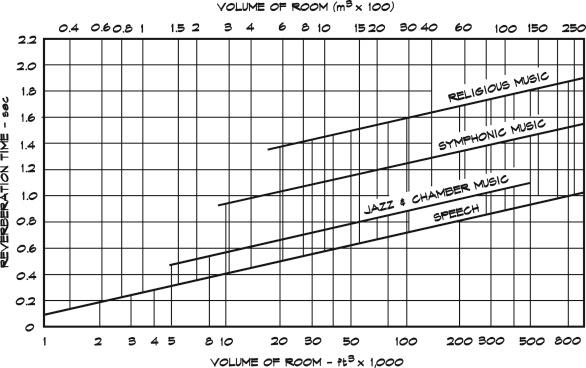

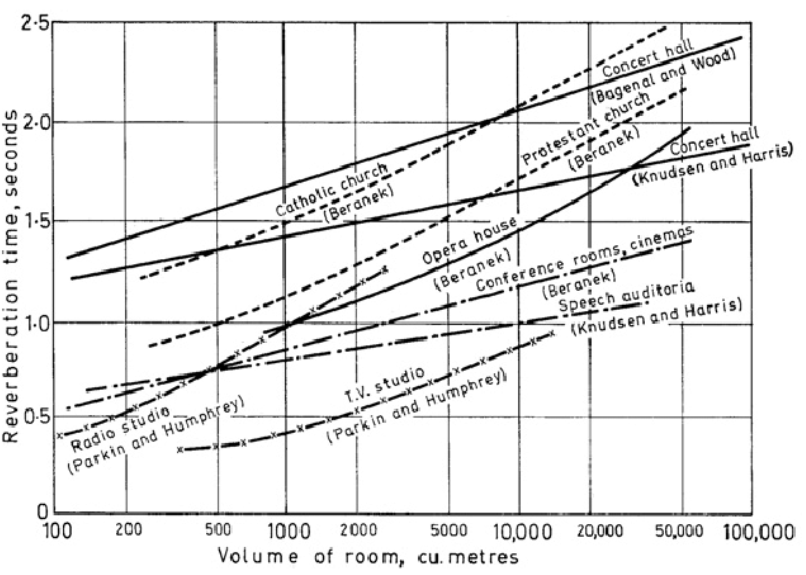

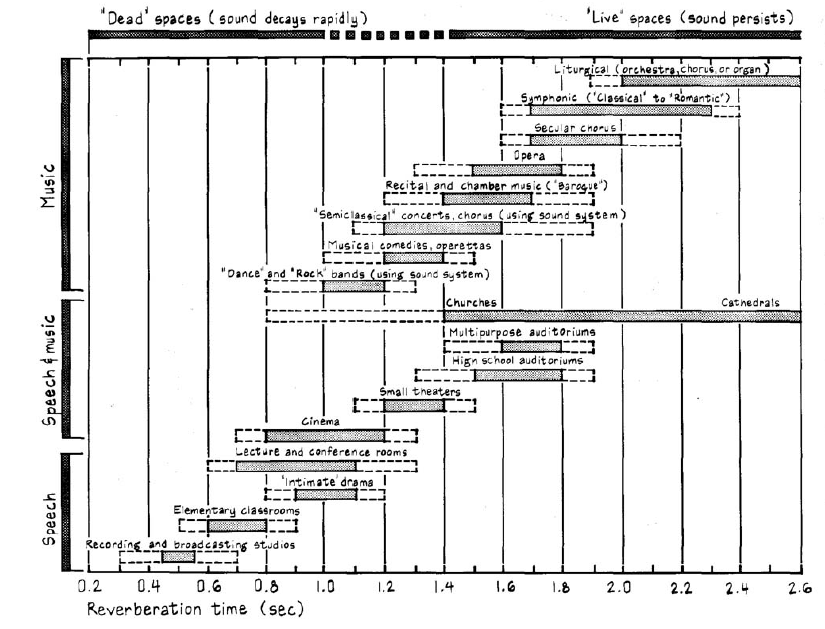

From the images we can see that values of beta should be chosen between 0.2 for small rooms (4 m per side) and 1.8 for very big rooms (30 m per side);

c = 340;                % Sound velocity (m/s)
fs = 16000;             % Sample frequency (samples/s)
r = [5, 1, 1];    % Receiver position [ x y z ] (m)
s = [5, 9, 1];      % Source position [ x y z ] (m)
L = [10, 10, 5];        % Room dimensions [ x y z ] (m)
beta = 1.2;             % Reverberation time (s)

% other optional parameters
nsample = fs*beta;      % Number of samples
mtype = 'omnidirectional';  % Type of microphone
order = -1;             % −1 equals maximum reflection order!
dim = 2;                % Room dimension
orientation = [0, 0];   % Microphone orientation [azimuth elevation] in radians
hp_filter = 1;          % Enable high-pass filter

Generated RIR (high computation, run only one time):

h = rir_generator(c, fs, r, s, L, beta); %nsample, mtype, order, dim, orientation, hp_filter);

Room Impulse Response Generator (Version 2.1.20141124) by Emanuel Habets
Copyright (C) 2003-2014 E.A.P. Habets, The Netherlands.


h = h';

Plot visual representation of the room:

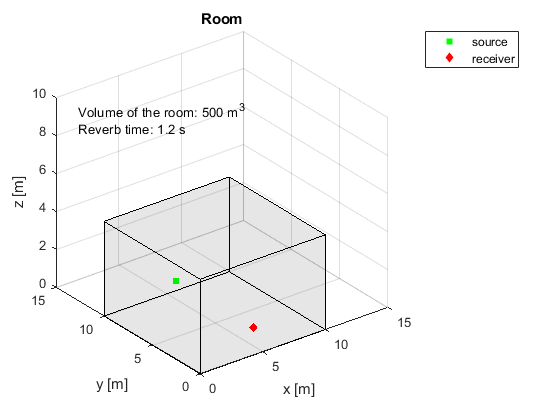

txt = {['Volume of the room: ',num2str(L(1)*L(2)*L(3)),' m^{3}'], ['Reverb time: ',num2str(beta),' s']};
figure
hold on

plotcube(L,[0,0,0],0.05,'k')
a = scatter3(s(1),s(2),s(3),'squareg','filled');
b = scatter3(r(1),r(2),r(3),'diamondr','filled');

text(1,L(2)+4,L(3)+4, txt )

xlabel('x [m]')
ylabel('y [m]')
zlabel('z [m]')

xlim([0,L(1)+5])
ylim([0,L(2)+5])
zlim([0,L(3)+5])

legend([a, b],'source','receiver')
grid on
title("Room")

Plot generated RIR:

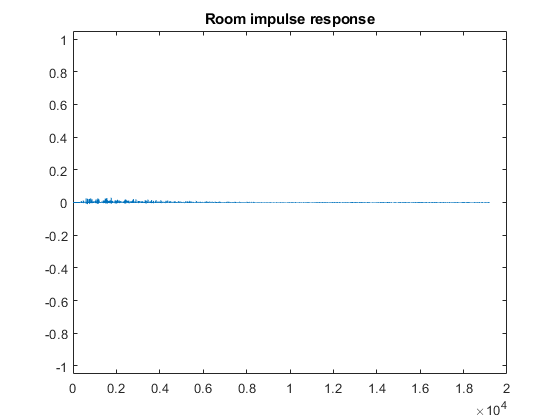

figure
plot(h)
title("Room impulse response")
ylim([-1.05,1.05])

Import a second RIR:

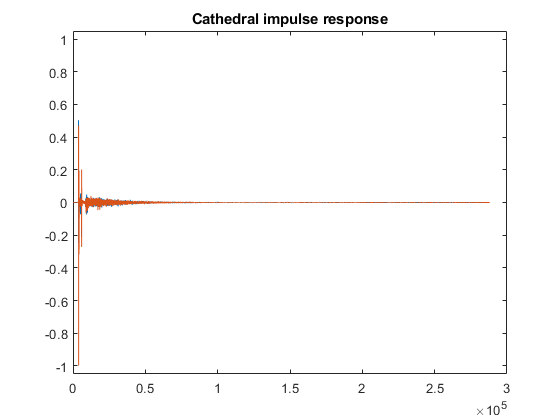

[h1,fs1] = audioread('1st-baptist-nashville/stereo/1st_baptist_nashville_balcony.wav');

figure
plot(h1)
ylim([-1.05,1.05])
title("Cathedral impulse response")

### Signal generation

Import a simple signal (handclap) to be reverberated and adapt the sampling frequency to match the RIR.

[sig,fs_sig] = audioread('voiced_a.wav'); 

Adjust the sampling frequency in order to have same $f_s$ of the RIR:

sig = resample(sig,fs,fs_sig);

Plot signals:

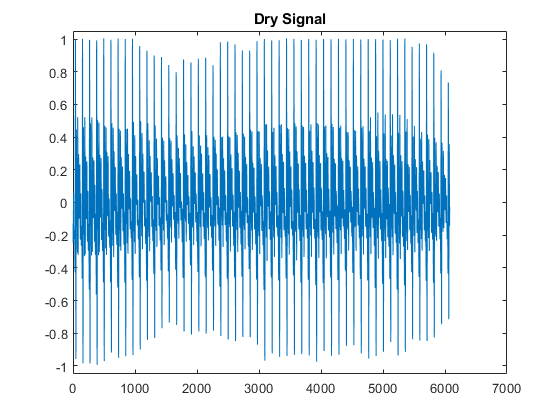

figure
plot(sig)
ylim([-1.05,1.05])
title("Dry Signal")

### Reverberation of signals

We have 2 alternatives: time convolution, fftfilt (OLA matlab)

#### Signal Convolution

Apply simple convolution in time domain

% rev_sig = conv(sig(:,1), h(:,1));

#### Function fftfilt

Apply OLA algorithm to compute convolution (multiplication in frequency domain)

rev_sig = fftfilt(sig(:,1), h(:,1));

### Results

Reverberated sound + audio samples

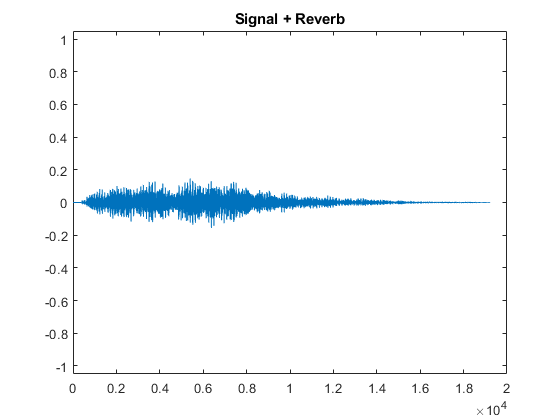

figure
plot(rev_sig)
ylim([-1.05,1.05])
title("Signal + Reverb")

Dry signal:

soundsc(sig, fs);
 

Reverberated signal:

soundsc(rev_sig, fs);
 

## Part 2: Dereverberation

### Kennedy1999iterative

#### Minimum-Phase/Allpass Decomposition: Standard Approach

Compute the DFT of $h\left(k\right)$ and find $H\left(n\right)$

H = fft(h.');

Compute the logarithm of frequency response as $\hat{H} \left(n\right)=\log \left|H\left(n\right)\right|+j\;\arg \left(H\left(n\right)\right)$

H_log = log(abs(H))+1i*angle(H);

Compute the even part of the complex cepstrum $\hat{h} \left(k\right)$ as $\hat{h_e } \left(k\right)=\frac{1}{N}\sum_{n=0}^{N-1} \log \left|H\left(n\right)\right|e^{j\left(\frac{2\pi \;}{N}\right)\textrm{kN}}$ where $k=0,1,2,\ldotp \ldotp \ldotp ,N-1$

% N = length(H);
% h_e = zeros(N,1);
% 
% for k=1:N
%     
%     for n=1:N
%         h_e(k) = h_e(k) + log(abs(H(n,1)))*exp(1i*(2*pi/N)*(k-1)*(n-1));
%     end
%     
%     h_e(k) = (1/N)*h_e(k);
% end


n = 0:length(H)-1;
k = n;
h_even=(1/length(n)).*(real(H_log).*exp(1i*(2*pi/length(n))*k*(n')));


#### Minimum-Phase/Allpass Decomposition: Novel Approach

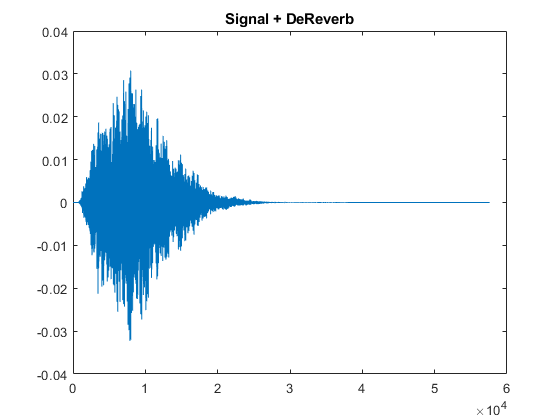

%cepstrum related to the minimum phase sequence
h_mp=zeros(1,length(n));
h_mp(1)=h_even(1);
h_mp(length(n)/2)=h_even(length(n)/2);
h_mp(2:(length(n)/2)-1)=2*h_even(2:(length(n)/2)-1);

 

%DFT of h_mp
H_mp=h_mp.*exp(-1i*(2*pi/length(n))*k*n');

 

%minimum phase part in linear domain
H_mp_ld=exp(H_mp);
inverse_H_mp_ld=1./H_mp_ld;
%calculating the remaining all-pass sequence
H_ap=H.*inverse_H_mp_ld;

 


h_dereverb_mp=ifft(H_mp_ld);
h_dereverb_ap=ifft(H_ap);

derev_sig=conv(rev_sig,h_dereverb_mp);
derev_sig=conv(derev_sig,h_dereverb_ap);

derev_sig1=fftfilt(rev_sig,h_dereverb_mp);
derev_sig1=fftfilt(derev_sig1,h_dereverb_ap);


plot(real(derev_sig))
title("Signal + DeReverb")

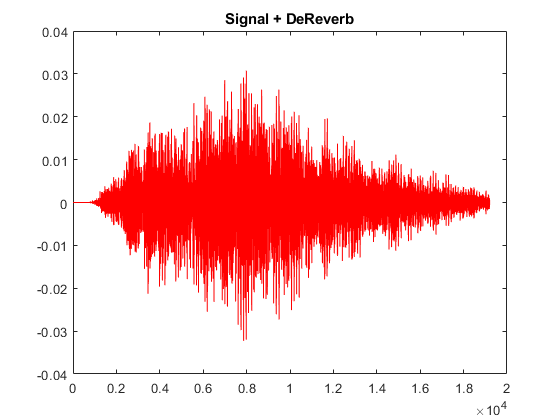


plot(real(derev_sig1),'r');
title("Signal + DeReverb")

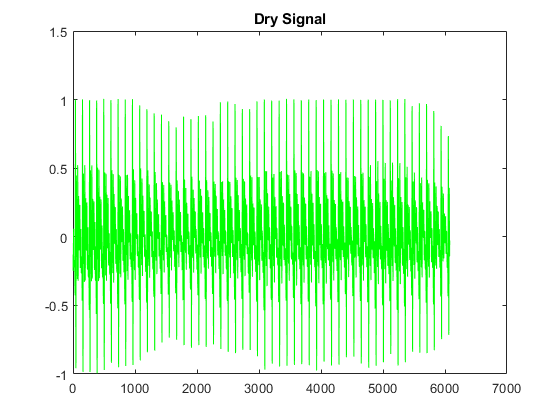

% 
plot(sig, 'g')
title("Dry Signal")

soundsc(real(derev_sig),fs);